% Cruise System

m=1000; b= 50;
A= -b/m; 
B= 1/m;
C= 1;
D= 0;

cruise_ss= ss(A,B,C,D)

cruise_ss =
 
  A = 
          x1
   x1  -0.05
 
  B = 
          u1
   x1  0.001
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.
모델 속성


s=tf('s');
P_cruise =1/(m*s+b)

P_cruise =
 
       1
  -----------
  1000 s + 50
 
연속시간 전달 함수입니다.
모델 속성


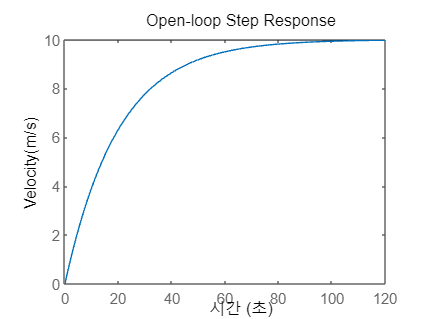

m=1000; b=50; u=500;

s=tf('s');
P_cruise=1/(m*s+b);
step(u*P_cruise)
title('Open-loop Step Response');
ylabel('Velocity(m/s)')

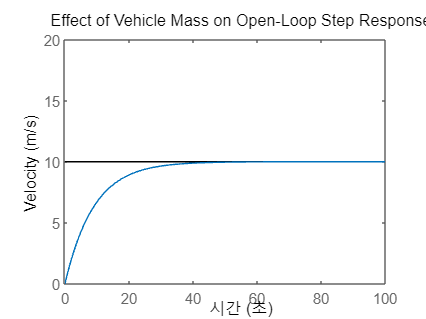

b=50;
u=500;
m=450;
P_cruise=1/(m*s+b);
step(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Mass on Open-Loop Step Response')
ylabel('Velocity (m/s)')

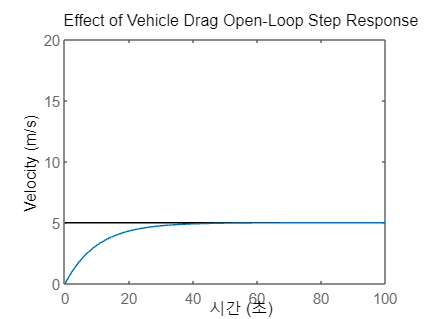

m=1000;
u=500;
b=100;
P_cruise=1/(m*s+b);
step(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Drag Open-Loop Step Response')
ylabel('Velocity (m/s)')

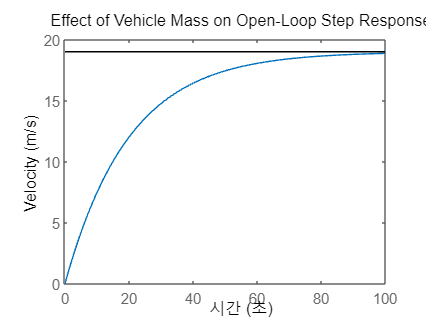

b=50;
m=1000;
u=950;
P_cruise=1/(m*s+b);
step(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Mass on Open-Loop Step Response')
ylabel('Velocity (m/s)')

J=0.01;
b=0.1;
K=0.01;
R=1;
L=0.5;
s=tf('s');
P_motor=K/((J*s+b)*(L*s+R)+K^2)

P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
연속시간 전달 함수입니다.
모델 속성


motor_ss=ss(P_motor)

motor_ss =
 
  A = 
           x1      x2
   x1     -12  -5.005
   x2       4       0
 
  B = 
        u1
   x1  0.5
   x2    0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.
모델 속성


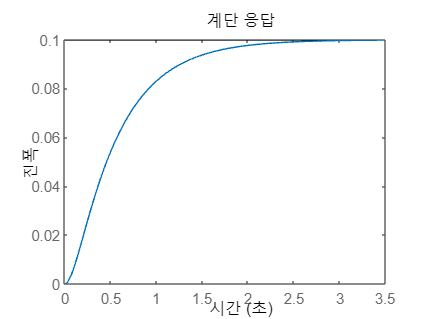


step(P_motor)